# Define parameter

close all;
clc;
clear;

syms initial_x initial_y initial_theta r L initial_omegaR initial_omegaL R omegaRmax omegaLmax dt our_pi
% our_pi =3.1415926535897932384626433832795028841;
initial_x = 3;
initial_y = 5;
initial_theta = pi/4;
r = 1;
L = 2;
initial_omegaR = 0;
initial_omegaL = 0;
dt = 0.01; %sampling time
R = 15;
omegaLmax = 100;

# Creating Trapezoid Velocity Representation for Omega

## For omegaL 

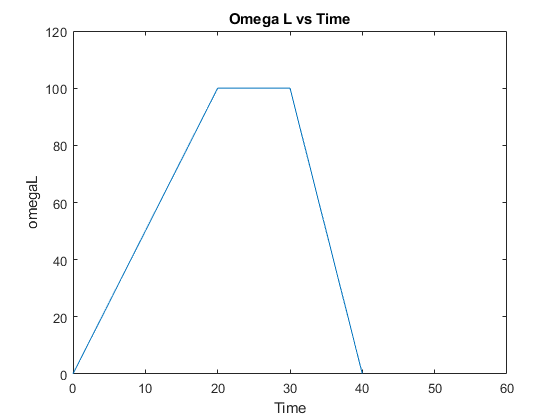

t_all = 0:dt:40;
t1 = 0:dt:20;
t2 = 20:dt:30;
t3 = 30:dt:40;

%create an array to hold omegaL values
omegaL = zeros(1, length(t_all));

omegaL(1) = initial_omegaL;

%for the first part of trapezoid
for i = 2:length(t1)
    omegaL(i) = (omegaLmax-initial_omegaL)/length(t1)*i+ initial_omegaL;
end

%second part
for i = length(t1):length(t1)+length(t2)-1
    omegaL(i) = omegaLmax;
end

%third part
for i = length(t1)+length(t2)-1:length(t1)+length(t2)+length(t3)-2
    omegaL(i) = 100- ((omegaLmax-0)/length(t3)*(i-length(t1)-length(t2)+1)); %% minus 0 because the final value will be 0
end

plot(t_all, omegaL)
xlabel('Time')
ylabel('omegaL')
title('Omega L vs Time')
xlim([0 60])
ylim([0 120])

## For OmegaR

Following the formula $\frac{\omega_R }{\omega_L }=\frac{2R-L}{2R\;+L}$

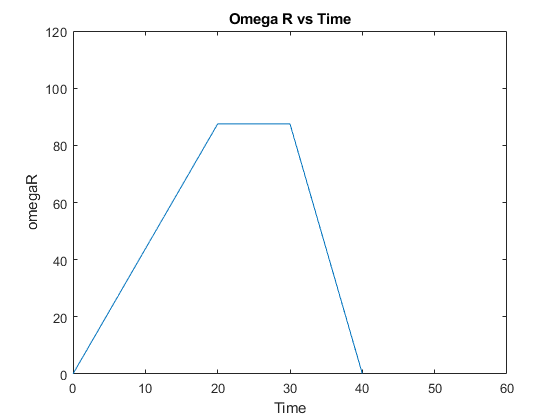

syms ratio

ratio = (2*R-L)/(2*R+L); 

%create an array to hold omegaR values
omegaR = zeros(1, length(t_all));

for i = 1:length(t_all)
    omegaR(i) = omegaL(i) * ratio;
end

plot(t_all, omegaR)
xlabel('Time')
ylabel('omegaR')
title('Omega R vs Time')
xlim([0 60])
ylim([0 120])

% %debugging ratio
% 
% ratio_array = zeros(1,length(t_all));
% for i = 1 :length(t_all)
%     ratio_array(i) = omegaR(i)/omegaL(i);
% end
% 
% plot(t_all,ratio_array);

# Model

xi ($\left.\xi \right)$with epsilon ($\left.\varepsilon \right)\;$

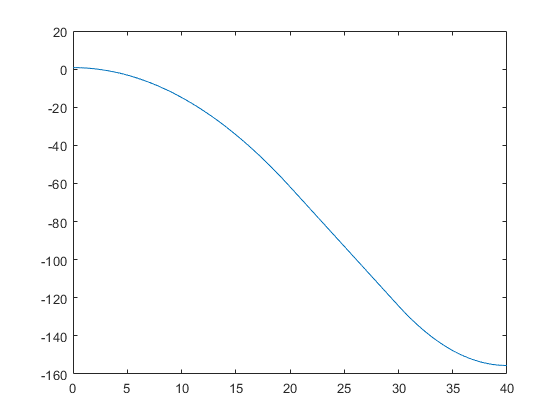

syms x_body_dot y_body_dot omega inverse_rotation_matrix x_world_dot y_world_dot xi_world_dot x_world y_world theta_array 

%create arrays to hold values
x_body_dot = zeros(1, length(t_all));
y_body_dot = zeros(1, length(t_all));
omega = zeros(1, length(t_all))     ;

%assign x_body_dot values
for i = 1 : length(t_all)
    x_body_dot(i) = r*omegaR(i)/2 + r*omegaL(i)/2;
end
%we dont need to assign y_body_dot because it's always zero (already zero
%in initialization)

%assign omega values
for i = 1 : length(t_all)
%     omega(i) = (r*omegaR(i)/L) - (r*omegaL(i)/L);
    omega(i) = (r/L)*(omegaR(i)-omegaL(i));
end

xi_body_dot = [x_body_dot; y_body_dot; omega];

%before we put inverse_rotation_matrix, we need to make an array of theta,
%because theta for every sampling time is different due to omegaR != omegaL
theta_array = zeros(1, length(t_all));
theta_array(1) = initial_theta;


%because we already got omega for every sampling time, we can assign theta
%value by integrate it 
for i = 2 : length(t_all)
    theta_array(i) = theta_array(i-1) + (omega(i)+omega(i-1))*dt/2;
end

plot(t_all, theta_array);

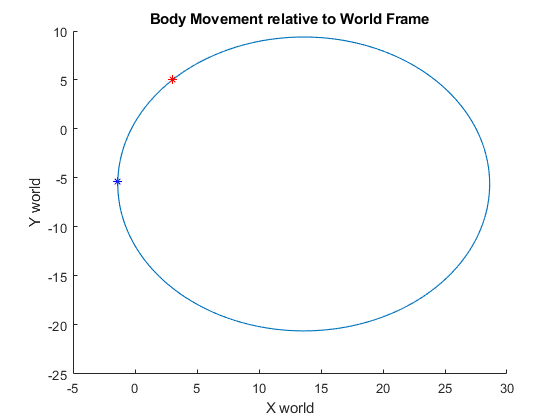


%inverse_rotation_matrix
%because theta for every sampling time is different, so does the
%inverse_rotation_matrix

%initialize 3 dimensional matrix to store inverse_rotation_matrix
inverse_rotation_matrix = zeros(3, 3 ,length(t_all));
%put initial value
inverse_rotation_matrix(:,:,1) = [cos(initial_theta) -sin(initial_theta) 0; sin(initial_theta) cos(initial_theta) 0; 0 0 1];
%update theta for every sampling time
for i = 2 : length(t_all)
    inverse_rotation_matrix(:,:,i) = [cos(theta_array(i)) -sin(theta_array(i)) 0; sin(theta_array(i)) cos(theta_array(i)) 0; 0 0 1];
end

%initialize xi_world_dot array
xi_world_dot = zeros(3, length(t_all));


for i= 1 : length(t_all)
    xi_world_dot(:,i) = inverse_rotation_matrix(:,:,i)* xi_body_dot(:,i);
end

%init x_world dot and y_world_dot
x_world_dot = zeros(1, length(t_all));
y_world_dot = zeros(1, length(t_all));

%assign value
for i = 1 : length(t_all)
    x_world_dot(i) = xi_world_dot(1,i);
    y_world_dot(i) = xi_world_dot(2,i);
end



%init x_world and y_world
x_world = zeros(1, length(t_all));
y_world = zeros(1, length(t_all));

% assign initial position, we dont need to assign theta, because it is
% already assigned in array theta_array

x_world(1) = initial_x;
y_world(1) = initial_y;

for i = 2: length(t_all)
    x_world(i) = x_world(i-1) + (x_world_dot(i)+x_world_dot(i-1))*dt/2;
    y_world(i) = y_world(i-1) + (y_world_dot(i)+y_world_dot(i-1))*dt/2;
end

% plot(x_world, y_world);
%plotting
plot3(x_world, y_world, theta_array)
xlabel("X world");
ylabel("Y world");
zlabel("Theta");
title('Body Movement relative to World Frame')

%set view to this value, so we can see the graph from up
% i dont know how to put theta information in 2D plot :(
view([0.0 90.00])

%put symbol to initial and final value
hold on
plot3(x_world(1),y_world(1), theta_array(1), 'r*'); %red star for initial value
plot3(x_world(length(t_all)), y_world(length(t_all)), theta_array(length(t_all)), 'b*'); % blue star for final value